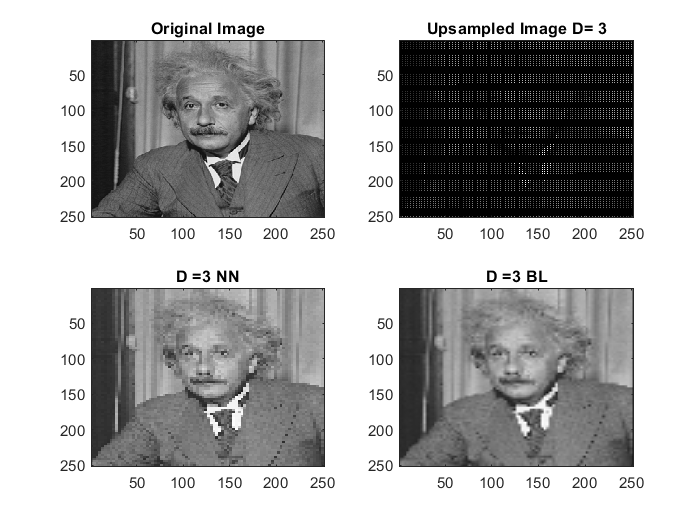


image = imread('einstein.tif');
[M, N] = size(image);

%% Downsampling the original image %%

Xdown_3 = image(1:3:end,1:3:end); % D = 3
Xdown_7 = image(1:7:end,1:7:end); % D = 7

%% Upsample the downsampled image %%

% D = 3
[m , n] = size(Xdown_3);
Xup_3 = zeros([m*3 n*3]);
Xup_3(1:3:end,1:3:end) = Xdown_3;

% D = 7
[p , q] = size(Xdown_7);
Xup_7 = zeros([p*7 q*7]);
Xup_7(1:7:end,1:7:end) = Xdown_7;

% D = 3 Nearest Neighbour Interpolation
kernel = [1 1 1]/3;
conv_1D = zeros(size(Xup_3));

% iterating the 1D filter along each row of the image
for k = 1:size(Xup_3,1)
    conv_1D(k,:) = conv(Xup_3(k,:),kernel,"same");
end

% iterating the 1D filter along each column of the image
for l = 1:size(Xup_3,2)
    conv_1D(:,l) = conv(conv_1D(:,l),transpose(kernel),"same");
end

% D = 7 Nearest Neighbour Interpolation
kernel_1 = [1 1 1 1 1 1 1]/7;
conv_1D_1 = zeros(size(Xup_7));

% iterating the 1D filter along each row of the image
for k = 1:size(Xup_7,1)
    conv_1D_1(k,:) = conv(Xup_7(k,:),kernel_1,"same");
end

% iterating the 1D filter along each column of the image
for l = 1:size(Xup_7,2)
    conv_1D_1(:,l) = conv(conv_1D_1(:,l),transpose(kernel_1),"same");
end

% D = 3 Bi-linear Interpolation
%% 2D-1 = 5

%%%% Pascals' triangle %%%%
%%%% Building a Pascal's triangle to build a 1D traingle filter 
%%%% Pascal's traingle is where the first and last element is always set to 1
%%%% The output matrix is with dimension of the filter 
%%%% The last row of the matrix obtained is divided by 2, excluding egdes

triangle_filter_1(1, 1) = 1;
triangle_filter_1(2, 1 : 2) = [1 1]; 
for dimension = 3 : 5
    triangle_filter_1(dimension, 1) = 1;   
    for c = 2 : dimension-1
        triangle_filter_1(dimension, c) = triangle_filter_1(dimension-1, c-1) + triangle_filter_1(dimension-1, c);
    end   
    triangle_filter_1(dimension, dimension) = 1;
end

pt_temp = triangle_filter_1(end:end, :);
pt_1 = [1 pt_temp(:,2:end-1)/2 1];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

kernel_3 = pt_1/3;
conv_BL_1 = zeros(size(Xup_3));

% iterating the 1D filter along each row of the image
for k = 1:size(Xup_3,1)
    conv_BL_1(k,:) = conv(Xup_3(k,:),kernel_3,"same");
end

% iterating the 1D filter along each column of the image
for l = 1:size(Xup_3,2)
    conv_BL_1(:,l) = conv(conv_BL_1(:,l),transpose(kernel_3),"same");
end

% D = 7 Bi-linear Interpolation
%% 2D-1 = 13

%%%% Pascals' triangle %%%%
triangle_filter_2(1, 1) = 1;
triangle_filter_2(2, 1 : 2) = [1 1]; 
for dimension = 3 : 13
    triangle_filter_2(dimension, 1) = 1;   
    for c = 2 : dimension-1
        triangle_filter_2(dimension, c) = triangle_filter_2(dimension-1, c-1) + triangle_filter_2(dimension-1, c);
    end   
    triangle_filter_2(dimension, dimension) = 1;
end

pt_temp1 = triangle_filter_2(end:end, :);
pt_1_1 = [1 pt_temp1(:,2:end-1)/2 1];
pt_1_1;
%%%%%%%%%%%%%%%%%%%%%%%%%%%

kernel_4 = pt_1_1/7;

conv_BL_2 = zeros(size(Xup_7));

% iterating the 1D filter along each row of the image
for k = 1:size(Xup_7,1)
    conv_BL_2(k,:) = conv(Xup_7(k,:),kernel_4,"same");
end

% iterating the 1D filter along each column of the image
for l = 1:size(Xup_7,2)
    conv_BL_2(:,l) = conv(conv_BL_2(:,l),transpose(kernel_4),"same");
end

% D = 3 outputs
if true
figure(1),
subplot(2,2,1), imagesc(image);colormap gray; title('Original Image');
subplot(2,2,2), imagesc(Xup_3);colormap gray; title('Upsampled Image D= 3');
subplot(2,2,3), imagesc(conv_1D);colormap gray; title('D =3 NN');
subplot(2,2,4), imagesc(conv_BL_1);colormap gray; title('D =3 BL');
end

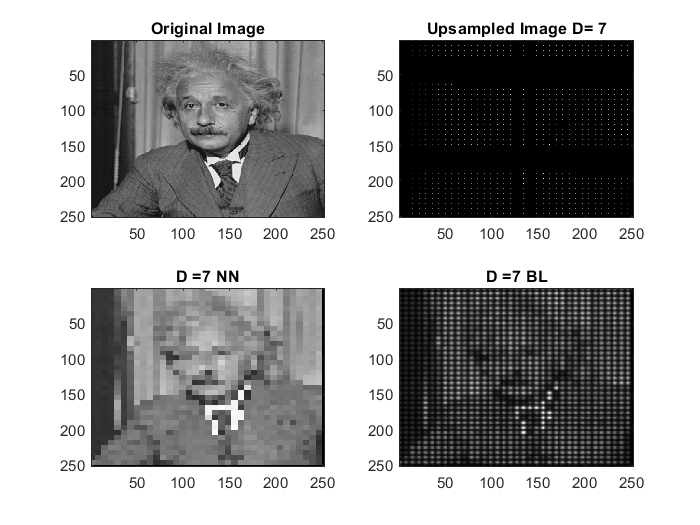

% D = 7 outputs
if true
figure(2),
subplot(2,2,1), imagesc(image);colormap gray; title('Original Image');
subplot(2,2,2), imagesc(Xup_7);colormap gray; title('Upsampled Image D= 7');
subplot(2,2,3), imagesc(conv_1D_1);colormap gray; title('D =7 NN');
subplot(2,2,4), imagesc(conv_BL_2);colormap gray; title('D =7 BL');
end

Observations: 

Lesser value of the dimension shows better interpolation during convolution of their layers. Pixel values are found to be distinct when it comes to higher dimension value. In both the case of D=3 and D=7 Nearest Neighbour interpolation is found to be efficient. When it comes to reconstruction of image, bi-linear interpolation works better due to its distint pixel allocation nature. 